# Normalized electric field strength as function of radial distance for HE11 mode in fiber taper

close all


## Input

diam = 1e-6;                 % Taper diameter
n_eff = 1.1716;                 % Effective refractive index 1.2246

## Parameters

lambda = 1.55e-6;               % Wavelength (m)
k0 = 2 * pi / lambda;           % Free-space wavenumber
n_co = 1.444;                   % Cladding refractive index
n_cl = 1.0;                     % Surrounding refractive index 
omega = 2 * pi * 3e8 / lambda;  % Angular frequency

b = diam / 2;                   % Cladding radius (m)
a = b / 15.24;                  % Core radius (m) 
beta = k0 * n_eff;              % Propagation constant: k0 * n_eff

v = 1;                          % Mode order = 1 for HE11
                                
% Derived quantities
U = b * sqrt(k0^2 * n_co^2 - beta^2);         % Core wavenumber for E_t 
W = b * sqrt(beta^2 - k0^2 * n_cl^2);         % Cladding decay constant for E_t 
V = 2*pi * b/lambda * sqrt(n_co^2 - n_cl^2);    % Cladding fiber parameter 

% Bessel coefficients
b1 = 1/(2*U*besselj(v,U)) * (besselj(v-1,U) - besselj(v+1,U));
b2 = -1/(2*W*besselk(v,W)) * (besselk(v-1,W) + besselk(v+1,W));
F2 = (V/(U*W))^2 * v/(b1 + b2);
a1 = (F2 - 1)/2;
a2 = (F2 + 1)/2;

% Initialize 2D amplitude map of field
% grid_size = sqrt(2) * MFD_um;    
grid_size = sqrt(2) * 1e-6;   
resolution = 2000;              
x = linspace(-grid_size, grid_size, resolution);
y = linspace(-grid_size, grid_size, resolution);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
Phi = atan2(Y, X);

% Initialize 2D field array
E_r_2D = zeros(size(R));
E_phi_2D = zeros(size(R));
E_z_2D = zeros(size(R));

## Boundary conditions

% % Evanescent field coefficients
% C_r = (-1 / besselj(v, U)) * ...
%     (a1 * besselj(v-1, U) + a2 * besselj(v+1, U)) / ...
%     (-U / (W * besselk(v, W)) * ...
%     (a1 * besselk(v-1, W) - a2 * besselk(v+1, W)));
% C_phi = (-1 / besselj(v, U)) * ...
%     (a1 * besselj(v-1, U) - a2 * besselj(v+1, U)) / ...
%     (-U / (W * besselk(v, W)) * ...
%     (a1 * besselk(v-1, W) + a2 * besselk(v+1, W)));


## Fields

% Cladding field
clad_idx = (R <= b);
E_r_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) + ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* cos(v * Phi(clad_idx));
E_phi_2D(clad_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(clad_idx) / b) - ...
     a2 * besselj(v+1, U * R(clad_idx) / b)) .* -sin(v * Phi(clad_idx));
E_z_2D(clad_idx) = -1j * U/(b*beta) * besselj(v, U * R(clad_idx) / b) / ...
    besselj(v,U) .* cos(v * Phi(clad_idx));

% Evanescent field 
ev_idx = (R > b);
E_r_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) - ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* cos(v * Phi(ev_idx));
E_phi_2D(ev_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(ev_idx) / b) + ...
     a2 * besselk(v+1, W * R(ev_idx) / b)) .* -sin(v * Phi(ev_idx));
E_z_2D(ev_idx) = -1j * U/(b*beta) * besselk(v, W * R(ev_idx) / b) / ...
    besselk(v,W) .* cos(v * Phi(ev_idx));

% Total field vector
E_vec = cat(3, E_r_2D, E_phi_2D, E_z_2D);
E_vec_cart = cat(3, ...
    E_r_2D .* cos(Phi) - E_phi_2D .* sin(Phi), ... 
    E_r_2D .* sin(Phi) + E_phi_2D .* cos(Phi), ...
    E_z_2D);

% Field magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

% Normalize total E-field
E_vec = E_vec / max(E_mag(:));
E_vec_cart = E_vec_cart / max(E_mag_cart(:));

% Recompute (compontent) magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

E_r = E_vec(:,:,1);
E_phi = E_vec(:,:,2);
E_z = imag(E_vec(:,:,3));

E_x = E_vec_cart(:,:,1);
E_y = E_vec_cart(:,:,2);
E_t = sqrt(E_vec(:,:,1).^2 + E_vec(:,:,2).^2);

disp(['Peak amplitude: ', num2str(max(E_mag(:))),' V/m']);

Peak amplitude: 1 V/m


## 2D Plot

% figure(1); hold on; box on;
% imagesc(x * 1e6, y * 1e6, E_mag);  
% viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
% viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
% axis equal tight;
% colormap default;
% color=colorbar;
% color.Label.String = 'Field strength (a.u.)';
% yline(0,'r','LineWidth',1.5);
% xline(0,'m','LineWidth',1.5);
% title(['|E| (HE_{11}), diam. ',num2str(2*b*1e6),' µm']);
% xlabel('x (µm)');
% ylabel('y (µm)');
% hold off;
% 
% matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\MFD_extract_2D_plot.tex',...
%     'relativeDataPath', 'Figures','showInfo', false,...
%     'extraAxisOptions', {'width=\linewidth'});


## 1D Slices

% Extract 1D slice from 2D grid (y = 0)
y_idx = round(resolution / 2);  % Middle row corresponds to y = 0

% E_r_slice = E_r(y_idx, :);
% E_phi_slice = E_phi(:, y_idx);
% E_z_slice = E_z(y_idx, :);

% % x-slice
% E_mag_slice = E_mag(y_idx,:);

% y-slice
E_mag_slice = E_mag(:,y_idx)';

% % Plot 
% figure; hold on
% plot(x * 1e6, E_r_slice, 'r', 'LineWidth', 2); 
% plot(x * 1e6, E_phi_slice, 'g', 'LineWidth', 2);
% plot(x * 1e6, E_z_slice, 'b', 'LineWidth', 2);
% xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
% title('1D Slices');
% xlabel('Radial distance (\mum)');
% ylabel('Field strength (V/m)');
% legend('E_r', 'E_\phi', 'E_z');
% grid on;


## Extract MFD from Gaussian fit

% % Define 2D Gaussian function
% gauss2D = @(params, X, Y) exp(-((X.^2) / (2 * params(2)^2) + (Y.^2) / (2 * params(3)^2)));
% 
% % Initial guess: [Amplitude, sigma_x, sigma_y]
% initial_params = [max(E_mag(:)), 1e-6, 1e-6];
% 
% % Fit 2D Gaussian to the mode profile
% [X_fit, Y_fit] = meshgrid(x, y);
% fit_params = lsqcurvefit(@(p, coords) gauss2D(p, coords(:,:,1), coords(:,:,2)), ...
%                          initial_params, cat(3, X_fit, Y_fit), E_mag);
% 
% % Compute fitted Gaussian profile
% E_gauss = gauss2D(fit_params, X_fit, Y_fit);
% E_gauss_x = E_gauss(y_idx, :);  % X slice at y = 0
% E_gauss_y = E_gauss(:, y_idx)'; % Y slice at x = 0 (transpose for row vector)
% E_gauss_slice = (E_gauss_x + E_gauss_y) / 2;
% 
% % Calculate MFD
% left_idx = find(x < 0);
% E_gauss_idx = E_gauss_slice(left_idx);
% x_idx = x(left_idx);
% y_intersect = 1 / exp(1);
% x_intersect = interp1(E_gauss_idx, x_idx, y_intersect, 'linear');
% MFD_ex = 2 * abs(x_intersect);  


## Extract MFD from graph intersect

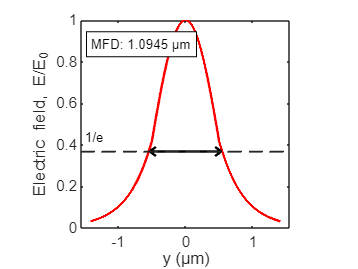

threshold = 1/exp(1);

% Find where it crosses 1/e
diff_above = E_mag_slice > threshold;
edges = diff(diff_above);
rising_edge_idx = find(edges == 1);
falling_edge_idx = find(edges == -1);

% Linear interpolation at 1/e level
x1 = rising_edge_idx(1); x2 = x1 + 1;
left_cross = x1 + (threshold - E_mag_slice(x1)) / (E_mag_slice(x2) - E_mag_slice(x1));

x1 = falling_edge_idx(end); x2 = x1 + 1;
right_cross = x1 + (threshold - E_mag_slice(x1)) / (E_mag_slice(x2) - E_mag_slice(x1));

% MFD in index units
MFD = right_cross - left_cross;

% Compute dx from x
dx = x(2) - x(1);

% Convert MFD to microns
MFD_um = MFD * dx;

figure; box on; hold on
plot(x * 1e6, E_mag_slice, 'r', 'LineWidth', 1.5); 
axis square
yline(threshold, '--');
    arrow_x = 0;
    arrow_y = threshold;   
    arrow_length = MFD_um*1e6/2+0.04;  
    quiver(arrow_x, arrow_y, arrow_length, 0, ...
    'Color', 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
    quiver(arrow_x, arrow_y, -arrow_length, 0, ...
    'Color', 'k', 'LineWidth', 1.5, 'MaxHeadSize', 0.5);
xlim([-sqrt(2)*MFD_um*1e6 sqrt(2)*MFD_um*1e6]);

% annotation('textbox', [0 1 0.2 0.1], 'String', ['MFD: ', num2str(MFD_um*1e6),' µm'], ...
%            'FitBoxToText', 'on', ...
%            'BackgroundColor', 'white', ...
%            'EdgeColor', 'black');
% 
% annotation('textbox', [0 threshold 0.2 0.1], 'String', '1/e', ...
%            'FitBoxToText', 'on', ...
%            'BackgroundColor', 'none');

text(-1.4, 0.92, ['MFD: ', num2str(MFD_um*1e6),' µm'], 'FontSize', 8, ...
    'HorizontalAlignment', 'left',...
    'VerticalAlignment','top',...
     'BackgroundColor', 'w','EdgeColor','k');
text(-1.5, threshold+0.07, '1/e', 'FontSize', 8, ...
    'HorizontalAlignment', 'left',...
     'BackgroundColor', 'none');

xlabel('y (µm)');
ylabel('Electric field, E/E_0');

matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\MFD_extract_y.tex',...
    'relativeDataPath', 'Figures','showInfo', false,...
    'extraAxisOptions', {'width=\linewidth'});